clear; clc;
mFile = '../mask2m_16_16.mat';
load(mFile); % mask2m 304x304x361

% Get the dimensions of the data
[h, w, c] = size(mask2m);


% Reshape the data into a 2D matrix
x = reshape(mask2m, h * w, c);



% Calculate the FFT 
fftx = fft(x, [], 2);
% Calculate normalized magnitude and angle
[mag, ang, frq] = freqMag(fftx);


## Sorting and Scaling Energy into Cummulativ Proportions


% Calculate the Energy Spectrum of fftx
eSpec = mag.^2; 
% Get the indices of the most important frequencies
[eSpecs, sFrq] = sort(eSpec(:, 2:end), 2, 'descend');
eSpecs = [eSpec(:,1) eSpecs];
sFrq = [zeros(size(sFrq, 1), 1) sFrq];
seSpec = prop(eSpecs, dim=2, cum=true);%cumsum(eSpecs, 2)./(sum(eSpecs, 2)*ones([1 size(eSpecs,2)]));

%imshow(seSpec(1:1000,:))

%surf(seSpec(1:100,:));shading interp

## Frequency of three-top Magnitude

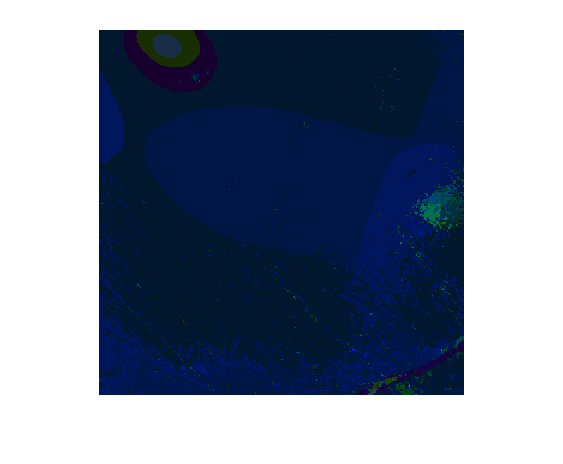


% Use the location of the three top values as color
y=sFrq(:, 2:4);
y=reshape(y, [h, w, 3]);
mat2img(y);

### Unique frequencies that add up to a limit

zlim = .95;
[px, py]=index2pos(find(seSpec(:,:)<zlim), h*w);
unique(py)

ans =      1
     2
     3
     4


### Extracing Base Frequencies

These are important frequencies found in the first few columns:

bf = sort(unique(sFrq(:,unique(py))));
length(bf)

ans = 12

bf

bf =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



csvwrite('SigFrqs95Lim.csv', bf)

### Extracting Energy based on the Significant Frequencies

SigFrqs = bf;
beSpec = eSpec(:, SigFrqs+1);


### Finding out How a Significant Energy Limit further Eliminates Observations

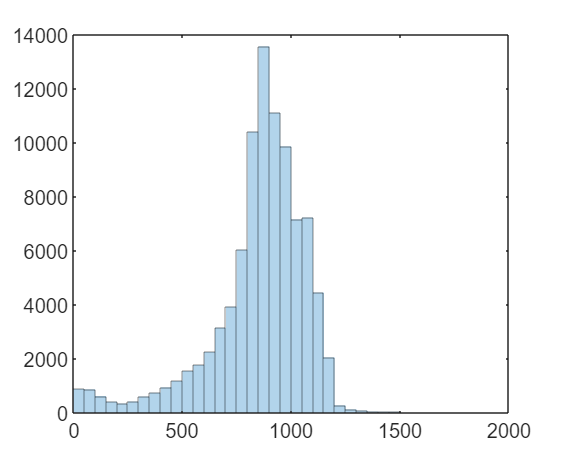

% Finding the limit for filtering values out
ubeSpec = unique(max(beSpec, [], 2));
histogram(ubeSpec, FaceAlpha=.3, EdgeAlpha=.3, BinWidth=50)
xlim([0, 2000])
hold on

Elim = 4;
histogram(ubeSpec(ubeSpec<Elim), "BinWidth", 50, "FaceColor","red", "EdgeColor","red")
hold off

### Finding Decimal value of a Frequency Signature based on the Significant Energy Limit

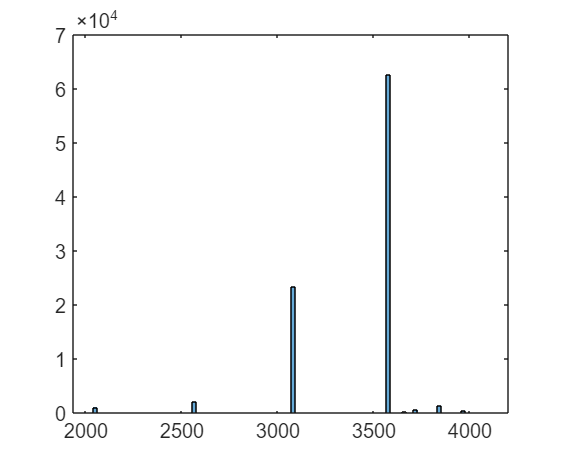

% Frequency Signature
beSig =  bin2dec(char(1.*(beSpec>Elim)+'0'));
%bin2dec('110000000000') % Mostly Expected
histogram(beSig, 100)

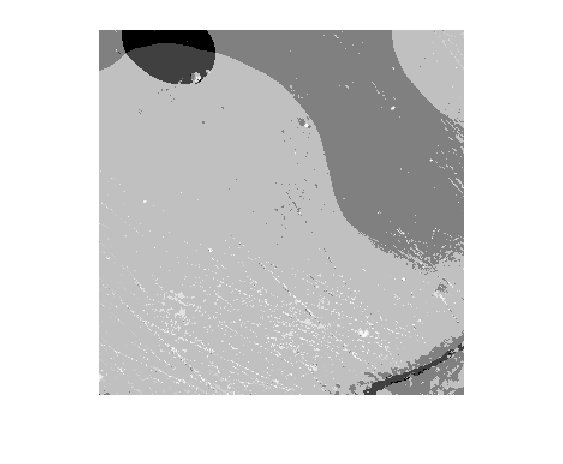

mat2img(reshape(beSig, [h w]));

### Finding clusters by Significant-Freq Value

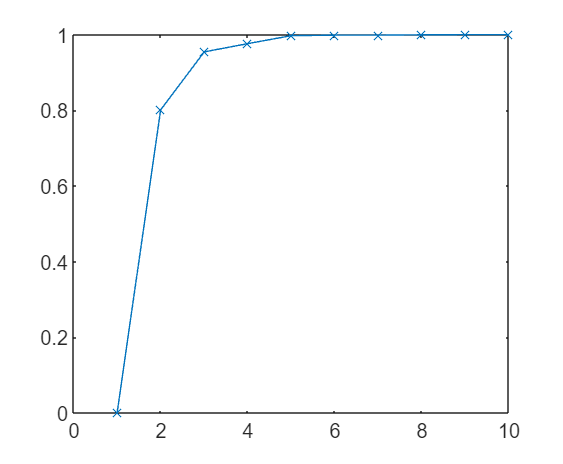


% Clsutering by the frequency signature
K = 10;
rsqs = zeros([K, 1]);
for k=1:K
    [~, ~, beSigWinSS] = kmeans(beSig, k);
    sst = sum(sum((beSig-mean(beSig)).^2));
    ssw = sum(beSigWinSS);
    rsqs(k) = 1-ssw/sst;
end

plot(rsqs, "-x")

rsqs

rsqs =     0.0000
    0.8008
    0.9541
    0.9759
    0.9970
    0.9983
    0.9984
    0.9993
    0.9997
    0.9997


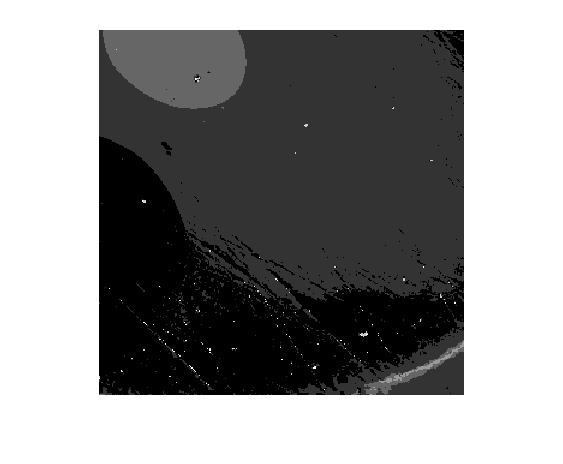

[beSigClusters, beSigCenters, beSigWinSS] = kmeans(beSig, 6,'Distance','cityblock');
mat2img(reshape(beSigClusters, [h w]));

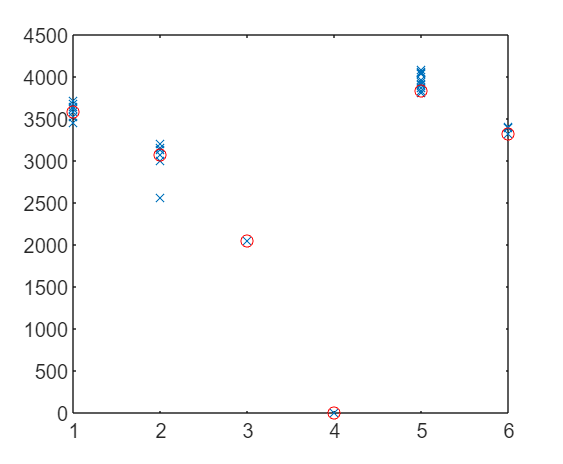


plot(beSigClusters, beSig, "x")
hold on
plot(beSigClusters, beSigCenters(beSigClusters), 'ro')
hold off

#### Testing Significant-Freq Value Clusters

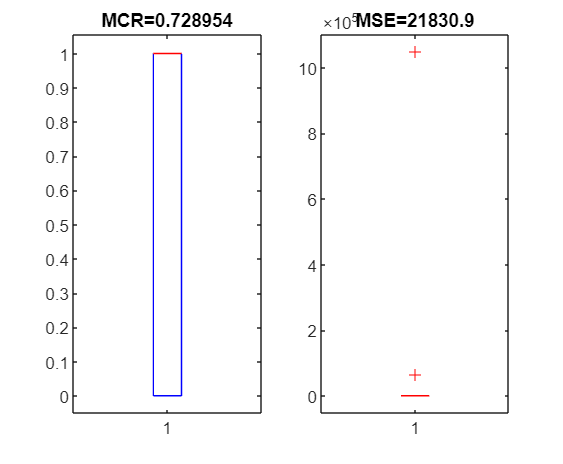


% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beSigCenters, 1) 1]);
for j=1:w*h
    [magj, ~, frqj] = freqMag(fft(x(j, :)));
    %sigFrqj = frqj(SigFrqs+1);
    %sigMagj = magj(sigFrqj+1);
    sigValj = bin2dec(char(1.*(magj(SigFrqs+1)>Elim)+'0'));
    ds = sum((beSigCenters-k1s*sigValj).^2, 2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beSigClusters(j));
end
subplot(1,2,1)
boxplot(mcr)
title(sprintf("MCR=%4g", mean(mcr)))
subplot(1,2,2)
boxplot(mseC)
title(sprintf("MSE=%4g", mean(mseC)))

subplot(1,1,1)


### Finding clusters by Significant-Freq Signature


% Clsutering by the frequency signature
K = 10;
rsqs = zeros([K, 1]);
beSigSig = beSpec>Elim

beSigSig = 92416×12 logical array
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0
   1   1   0   0   0   0   0   0   0   0   0   0


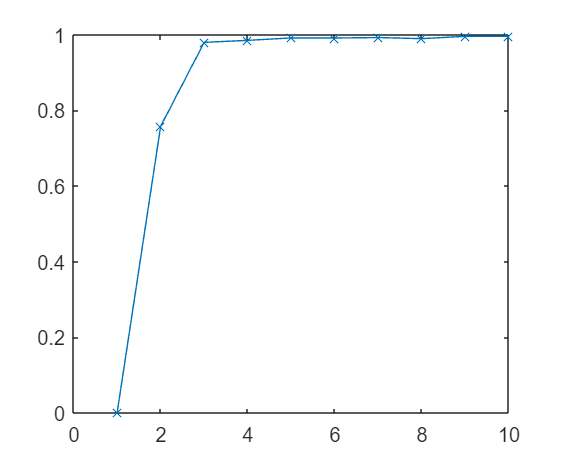

for k=1:K
    [~, ~, beSigWinSS] = kmeans(beSigSig, k);
    sst = sum(sum((beSigSig-mean(beSigSig)).^2));
    ssw = sum(beSigWinSS);
    rsqs(k) = 1-ssw/sst;
end

plot(rsqs, "-x")

rsqs

rsqs =    -0.0000
    0.7575
    0.9793
    0.9847
    0.9910
    0.9908
    0.9920
    0.9892
    0.9953
    0.9956


[beSigSigClusters, beSigSigCenters, beSigSigWinSS] = kmeans(beSigSig, 4);
mat2img(reshape(beSigClusters, [h w]));

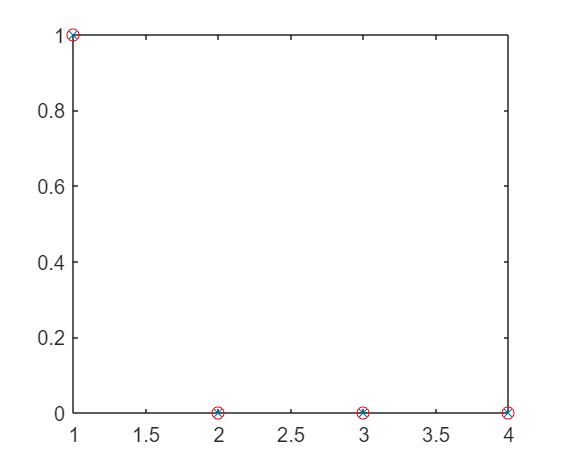


dm = 3;
plot(beSigSigClusters, beSigSig(:,dm), "x")
hold on
plot(beSigSigClusters, beSigSigCenters(beSigSigClusters, dm), 'ro')
hold off

#### Testing Significant-Freq Value Clusters


% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beSigSigCenters, 1) 1]);
for j=1:w*h
    [magj, ~, frqj] = freqMag(fft(x(j, :)));
    %sigFrqj = frqj(SigFrqs+1);
    %sigMagj = magj(sigFrqj+1);
    sigSigj = magj(SigFrqs+1)>Elim;
    ds = sum((beSigSigCenters-k1s*sigSigj).^2, 2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beSigSigClusters(j));
end
subplot(1,2,1)
boxplot(mcr)
title(sprintf("MCR=%4g", mean(mcr)))
subplot(1,2,2)
boxplot(mseC)
title(sprintf("MSE=%4g", mean(mseC)))
subplot(1,1,1)


ans = 0.7282

ans = 0.0209

### Finding Clsuters by the Magnitude


K = 10;
rsqs = zeros([K, 1]);
for k=1:K
    [~, ~, beMagWinSS] = kmeans(beSpec, k);
    sst = sum(sum((beSpec-mean(beSpec)).^2));
    ssw = sum(beMagWinSS);
    rsqs(k) = 1-ssw/sst;
end

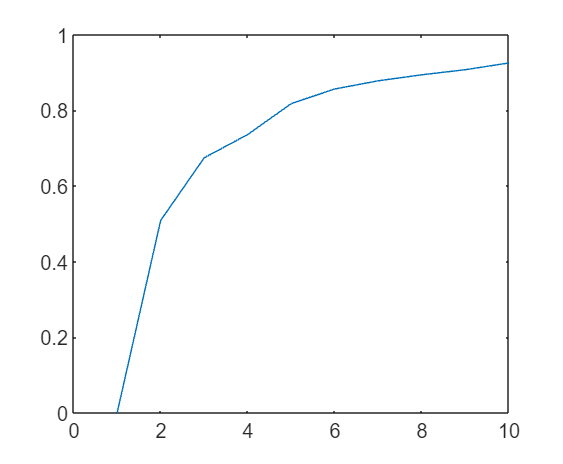

plot(rsqs)

rsqs

rsqs =     0.0000
    0.5086
    0.6743
    0.7357
    0.8175
    0.8562
    0.8778
    0.8936
    0.9071
    0.9249


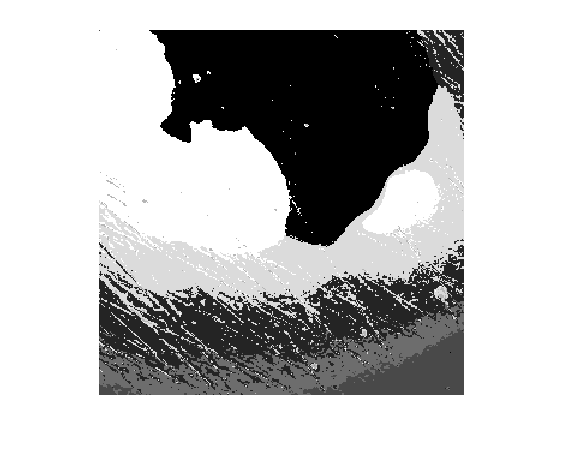

[beMagClusters, beMagCenters, ~] = kmeans(beSpec, 8);
mat2img(reshape(beMagClusters, [h w]));

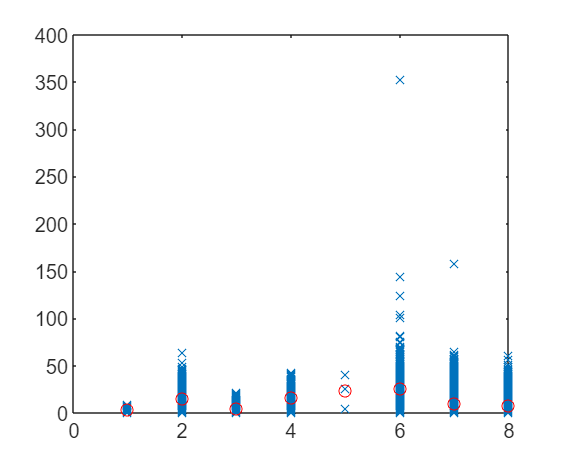


dm = 2;
plot(beMagClusters, beSpec(:,dm), "x")
hold on
plot(beMagClusters, beMagCenters(beMagClusters, dm), 'ro')
hold off

#### Testing Mag Clusters

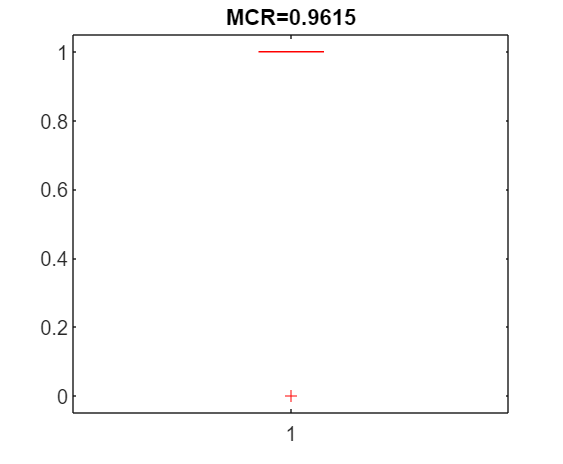

ans = 0.9615

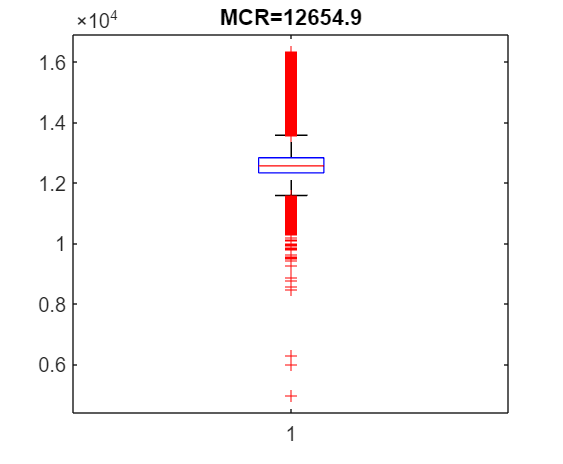


% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beMagCenters, 1) 1]);
for j=1:w*h
    magj = freqMag(fft(x(j, :)));
    sigMagj = magj(SigFrqs+1);
    ds = sum((beMagCenters-k1s*sigMagj).^2, 2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beMagClusters(j));
end
subplot(1,2,1)
boxplot(mcr)
title(sprintf("MCR=%4g", mean(mcr)))
subplot(1,2,2)
boxplot(mseC)
title(sprintf("MSE=%4g", mean(mseC)))
subplot(1,1,1)


### Finding Clusters using both Significant Frequencies Signature and Magnitude


K = 10;
%eSepcSigD = [sbeSpec beSig];
avgMag = mean(mean(beSpec));
eSepcSigD = [beSpec avgMag.*(beSpec>Elim)];
% for j=1:size(eSepcSigD, 2)
%     eSepcSigD(:,j) = rescale(eSepcSigD(:,j)); % Scaling each column to 0 to 1
% end

rsqs = zeros([K, 1]);
for k=1:K
    [~, ~, beMagFrqWinSS] = kmeans(eSepcSigD, k);
    sst = sum(sum((eSepcSigD-mean(eSepcSigD)).^2));
    ssw = sum(beMagFrqWinSS);
    rsqs(k) = 1-ssw/sst;
end

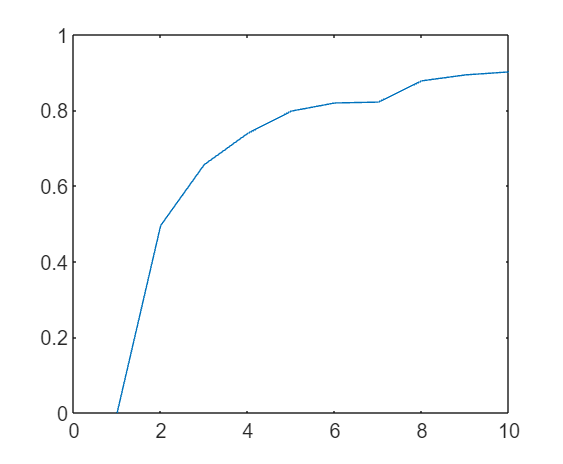

plot(rsqs)

rsqs

rsqs =    -0.0000
    0.4950
    0.6559
    0.7388
    0.7976
    0.8192
    0.8215
    0.8777
    0.8933
    0.9012


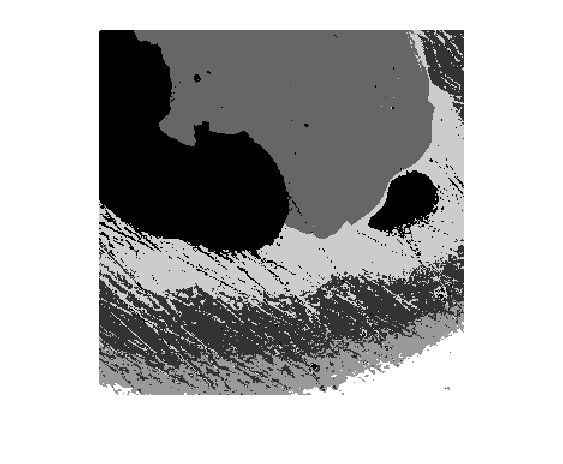

[beMegSigClusters, beMefSigCenters, ~] = kmeans(eSepcSigD, 6);
mat2img(reshape(beMegSigClusters, [h w]));

#### Testing Mag & Freq Signature Clusters

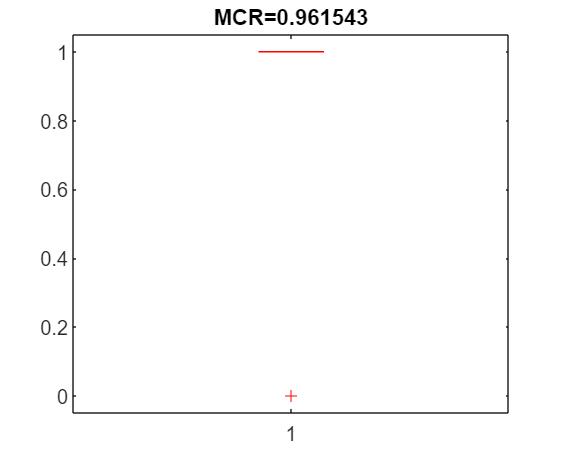

ans = 0.9615

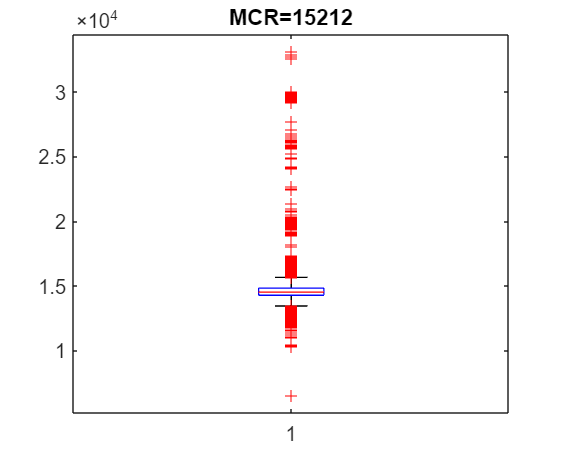


% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beMefSigCenters, 1) 1]);
for j=1:w*h
    magj = freqMag(fft(x(j, :)));
    sigMagj = magj(SigFrqs+1);
    ds = sum((beMefSigCenters-k1s*[sigMagj avgMag.*(sigMagj>Elim)]).^2, 2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beMegSigClusters(j));
end
subplot(1,2,1)
boxplot(mcr)
title(sprintf("MCR=%4g", mean(mcr)))
subplot(1,2,2)
boxplot(mseC)
title(sprintf("MSE=%4g", mean(mseC)))
subplot(1,1,1)


### Finding Clusters using both Significant Frequencies Signature and Scaled Magnitude

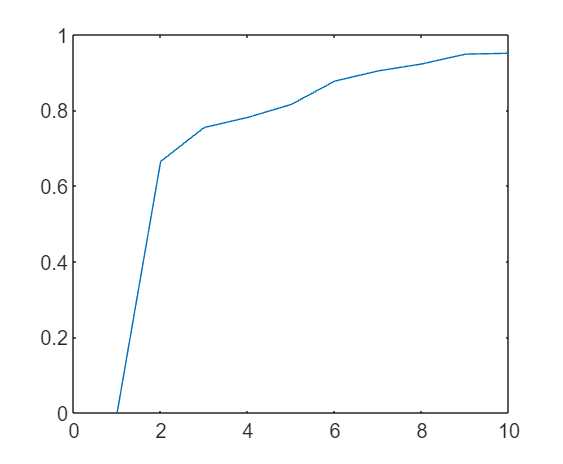


K = 10;
eSepcSigS = [prop(beSpec, dim=2) (beSpec>Elim)];
rsqs = zeros([K, 1]);
for k=1:K
    [~, ~, beMagFrqWinSS] = kmeans(eSepcSigS, k);
    sst = sum(sum((eSepcSigS-mean(eSepcSigS)).^2));
    ssw = sum(beMagFrqWinSS);
    rsqs(k) = 1-ssw/sst;
end
plot(rsqs)

rsqs

rsqs =    -0.0000
    0.6646
    0.7543
    0.7810
    0.8152
    0.8770
    0.9039
    0.9223
    0.9482
    0.9505


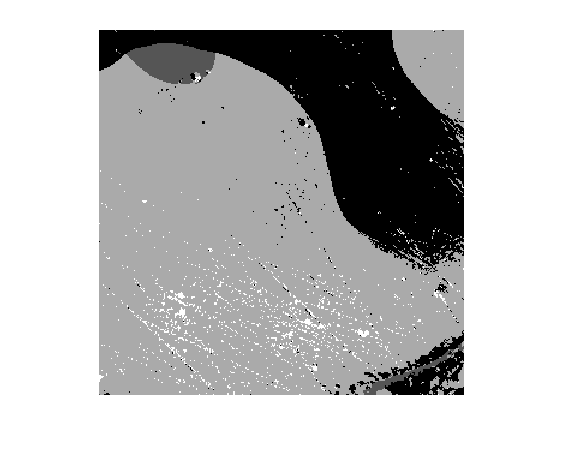

[beMegSigClusters, beMefSigCenters, ~] = kmeans(eSepcSigS, 4);
mat2img(reshape(beMegSigClusters, [h w]));

#### Testing Scaled Mag & Freq Signature Clusters

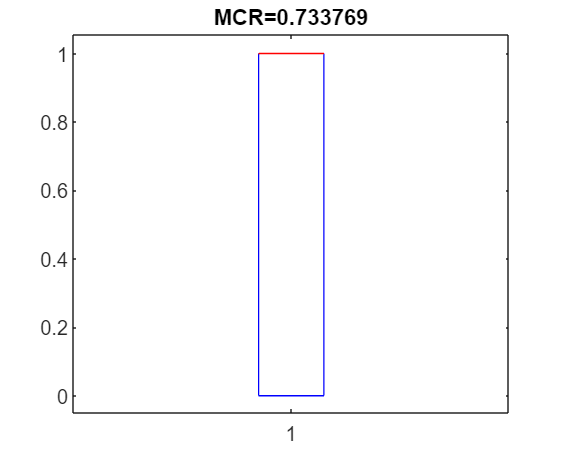

ans = 0.7338

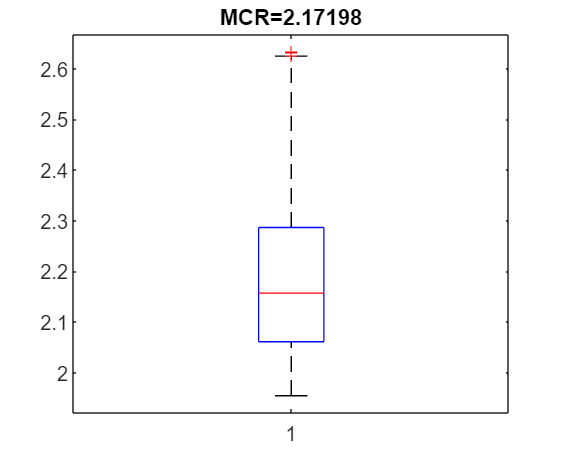


% Test
mseC = zeros(h*w, 1);
mse = zeros(h*w, 1);
mcr = zeros(h*w, 1);
k1s = ones([size(beMefSigCenters, 1) 1]);
for j=1:w*h
    magj = freqMag(fft(x(j, :)));
    sigMagj = prop(magj(SigFrqs+1));
    ds = sum((beMefSigCenters-k1s*[sigMagj (sigMagj>Elim)]).^2, 2);
    [m, i] = min(ds);
    mseC(j) = m;
    mcr(j) = 1-(i==beMegSigClusters(j));
end
subplot(1,2,1)
boxplot(mcr)
title(sprintf("MCR=%4g", mean(mcr)))
subplot(1,2,2)
boxplot(mseC)
title(sprintf("MSE=%4g", mean(mseC)))
subplot(1,1,1)
